## Dynamical analysis

We plan to extend the definition provided for kinematic analysis for data required by dynamical analysis (inertias and forces).

Next we will form equations of motion for the system of unconstrained bodies.

Finally we will solve the general multibody equations of motion.

### Bodies, inertias, and coordinates

Solve the pendulum as multibody system and compare results with differential equation 


$$I_0 \theta^¨ =-\textrm{mg}\frac{l}{2}\sin \theta$$


% Pendulum data
m = 2.0;
l = 1.0;
theta0 = deg2rad(90);
g = 9.81;
Io = m*l^2/12;
tf = 2.0;


Solution using 1 dof differential equations

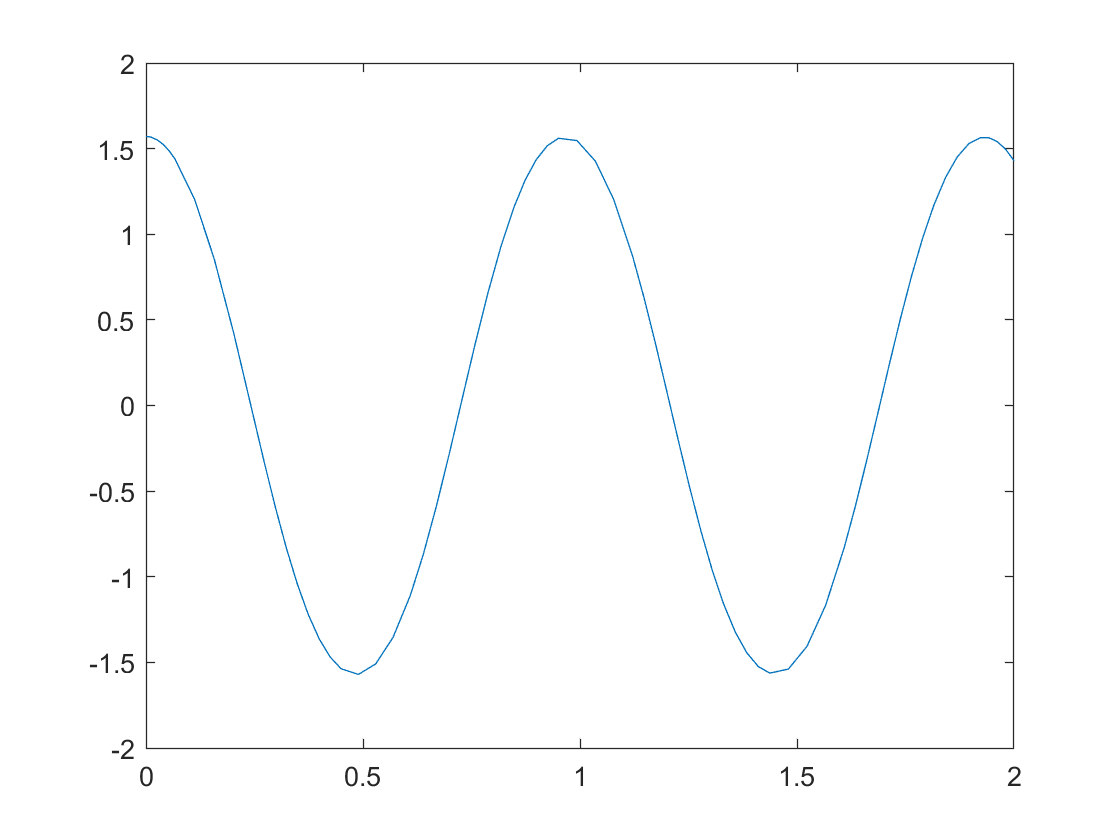

y0 = [theta0; 0.0]; % angle and its initial velocity

odefun = @(t, y) [y(2); -m * g * l / 2 * sin(y(1)) / Io];
tspan = [0.0, tf];
[t, y] = ode45(odefun, tspan, y0);

plot(t, y(:, 1))

Solution using MBD method

mbs = init_mbs();
mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "beam1", 0.5*l*cos(theta0), 0.5*l*sin(theta0), theta0, ...
    'm', m, 'Ic', Io);
mbs = add_body(mbs, "mass", -0.1,0, 'm', 1.0, 'Ic', 0.1)

mbs = struct with fields:
     bodies: [1×3 struct]
     joints: [1×1 struct]
         nq: 9
         nc: 0
    gravity: []
     forces: [1×1 struct]
     balpha: 5
      bbeta: 5



% Simple joints
mbs = add_simple_joint(mbs, "groundx", "ground", "x", 0);
mbs = add_simple_joint(mbs, "groundy", "ground", "y", 0);
mbs = add_simple_joint(mbs, "groundangle", "ground", "fi", 0);

mbs = add_revolute(mbs, "revO", "ground", [0; 0], "beam1", [-0.5 * l, 0.0]);
mbs = add_revolute(mbs, "rev_mass", "beam1", [0.5 * l; 0], "mass", [0.0, 0.0]);


f = -10;
k = 7;
% Add rotational spring
mbs = add_rotational_spring(mbs,"spring1", "ground","beam1",[deg2rad(10),k]);
mbs = add_scaled_force(mbs,"scaled_force","mass",[0,f])

mbs = struct with fields:
     bodies: [1×3 struct]
     joints: [1×1 struct]
         nq: 9
         nc: 7
    gravity: []
     forces: [1×1 struct]
     balpha: 5
      bbeta: 5




q0 = initial_position(mbs);
qd0 = zeros(size(q0));
h = 0.002;
accfun = @(t,q)acceleration(mbs, q, t);
[t2, Q, Qp] = eqn_of_motion(accfun, tf, q0, qd0, h);

54 successful steps
3 failed attempts
343 function evaluations


Compare results with reference

% Calculate refrence
E = 200; % Young's Modulus of Structural ASTM-A36 
x = linspace(0,f, length(t));
d = ((x ) * (l).^3)/ (3*E*Io);


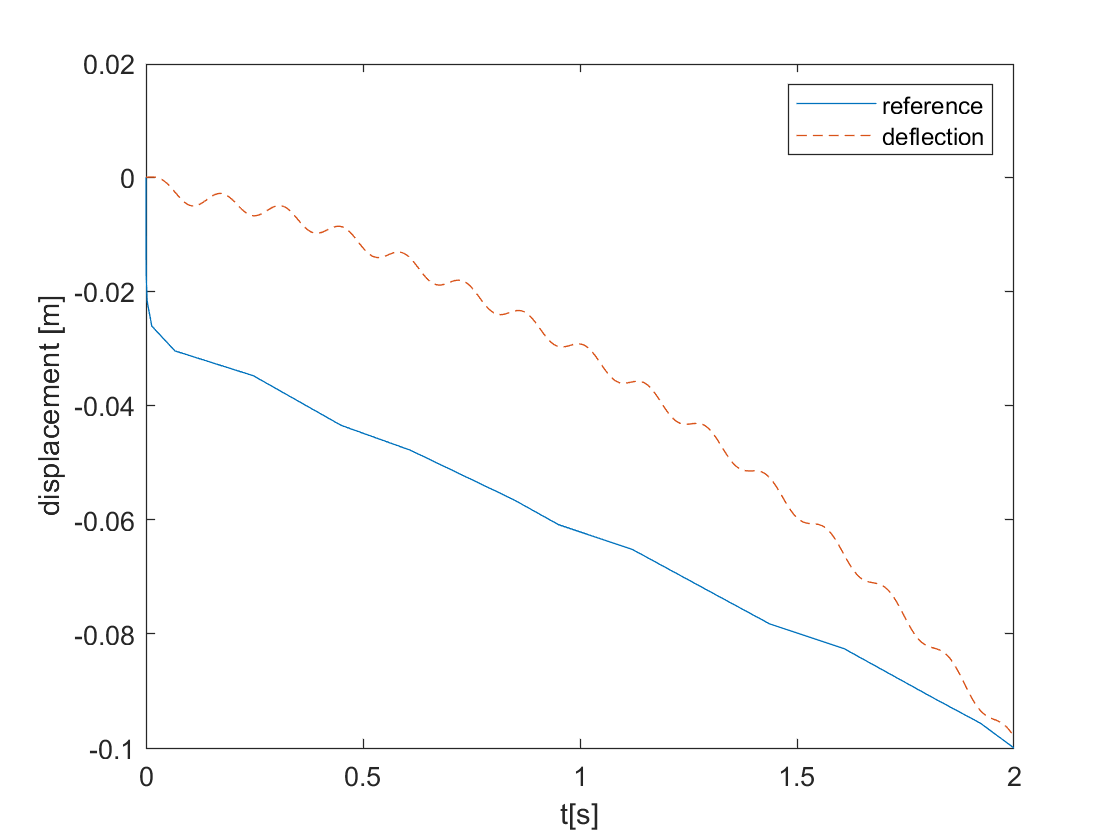

plot(t,d ,t2, Q(:, 7) + 0.1, '--');
legend('reference', 'deflection')
xlabel('t[s]')
ylabel('displacement [m]')
exportgraphics(gcf,'output-cantilever-single.png','Resolution',300)